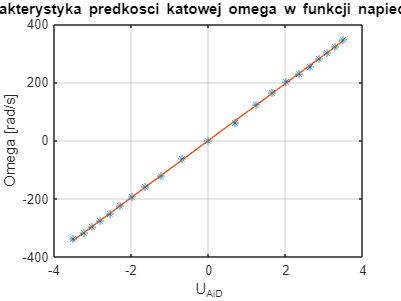

u = -1:0.1:1;
u_AiD = [-3.5, -3.2, -3, -2.8, -2.54, -2.28, -1.96, -1.62, -1.21, -0.68, 0, 0.69, 1.24, 1.66, 2.01, 2.36, 2.64, 2.88, 3.09, 3.28, 3.5];
u_M = [-1.67, -1.57, -1.47, -1.37, -1.25, -1.1, -0.95, -0.79, -0.59, -0.3, 0, 0.3, 0.61, 0.81, 1, 1.15, 1.27, 1.4, 1.5, 1.61, 1.72];
n = (u_M/0.52)*1000;
w = (pi*n)/30;

p = polyfit(u_AiD,w,1);
x_fit = linspace(min(u_AiD),max(u_AiD),100);
y_fit = polyval(p,x_fit);

plot(u_AiD, w, "*", x_fit,y_fit);
xlabel('U_{AiD}');
ylabel('Omega [rad/s]');
grid on;
title("Charakterystyka predkosci katowej omega w funkcji napiecia U_{AiD}")

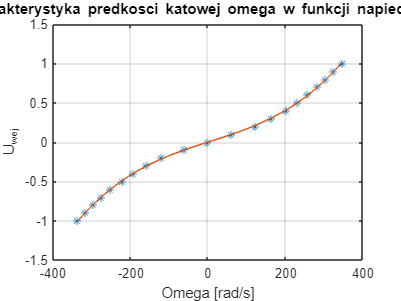


p2 = polyfit(w,u,3);
x_fit2 = linspace(min(w),max(w),100);
y_fit2 = polyval(p2,x_fit2);
plot(w,u,"*",x_fit2,y_fit2);
title("Charakterystyka predkosci katowej omega w funkcji napiecia U_{AiD}")
xlabel('Omega [rad/s]');
ylabel('U_{wej}');
grid on;